# Study of Income Dataset

Clear workspace

clear all; clc; close all;

## Initialize all

income = readtable('income.csv');

class(income)

ans = 'table'


income.Properties;

head(income);

    ID    Income    Age    Education    Gender
    __    ______    ___    _________    ______

    1      113      69        12          1   
    2       91      52        18          0   
    3      121      65        14          0   
    4       81      58        12          0   
    5       68      31        16          1   
    6       92      51        15          1   
    7       75      53        15          0   
    8       76      56        13          0   




size(income)

ans =         1500           5


income.Properties.VariableNames

ans = 1×5 cell array
    {'ID'}    {'Income'}    {'Age'}    {'Education'}    {'Gender'}


## Stats of the data

s = summary(income);
% Compute some stats of the thada grouped by category
groupsummary(income,'Gender','mean')

ans = 2×6 table
    Gender    GroupCount    mean_ID    mean_Income    mean_Age    mean_Education
    ______    __________    _______    ___________    ________    ______________

      0          765        748.27       76.869        43.987         14.694    
      1          735        752.82       75.067        43.161         14.668    


groupsummary(income,'Gender','std')

ans = 2×6 table
    Gender    GroupCount    std_ID    std_Income    std_Age    std_Education
    ______    __________    ______    __________    _______    _____________

      0          765        429.54      20.423      15.174        2.7521    
      1          735        437.17      19.532      15.164        2.6336    


groupsummary(income,'Gender','var')

ans = 2×6 table
    Gender    GroupCount      var_ID      var_Income    var_Age    var_Education
    ______    __________    __________    __________    _______    _____________

      0          765        1.8451e+05      417.11      230.24        7.5739    
      1          735        1.9112e+05      381.51      229.94         6.936    



gs = groupsummary(income,'Gender','all') % All stats

gs = 2×46 table
    Gender    GroupCount    mean_ID      sum_ID      min_ID    max_ID    range_ID    median_ID    mode_ID      var_ID      std_ID    nummissing_ID    nnz_ID    mean_Income    sum_Income    min_Income    max_Income    range_Income    median_Income    mode_Income    var_Income    std_Income    nummissing_Income    nnz_Income    mean_Age    sum_Age    min_Age    max_Age    range_Age    median_Age    mode_Age    var_Age    std_Age</

gs.var_Income

ans =   417.1059
  381.5064


## Plot exploration

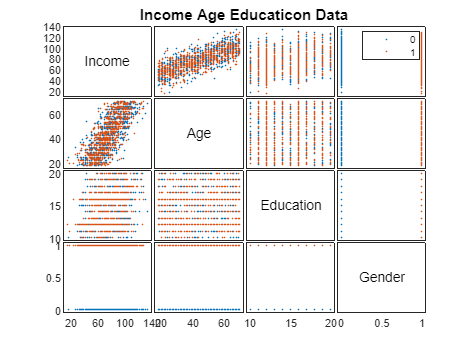

X = [income.Income income.Age income.Education income.Gender];
color = lines(2);
xnames = income.Properties.VariableNames(2:end);

[h, ax] = gplotmatrix(X,[],income.Gender,color,[],[],[],'variable',xnames);
title('Income Age Educaticon Data')

## Regression

### regress

Y = income.Income;
X = [ones(size(income,1),1) income.Age income.Education income.Gender];
[b,bint,r,rint,stats] = regress(Y,X);
[b,bint]

ans =     7.2630    3.4267   11.0993
    0.9952    0.9548    1.0356
    1.7579    1.5307    1.9851
   -0.9343   -2.1581    0.2894


stats

stats =     0.6364  872.9685         0  145.7901


### fitlm

lm = fitlm(X(:,2:end),Y)

lm = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate       SE        tStat       pValue   
                   ________    ________    _______    ___________

    (Intercept)       7.263      1.9557     3.7137     0.00021178
    x1               0.9952    0.020573     48.373    3.3868e-308
    x2               1.7579     0.11581     15.179     1.6482e-48
    x3             -0.93433     0.62388    -1.4976        0.13444


Number of observations: 1500, Error degrees of freedom: 1496
Root Mean Squared Error: 12.1
R-squared: 0.636,  Adjusted R-Squared: 0.636
F-statistic vs. constant model: 873, p-value = 0


ypred = predict(lm,X(:,2:end))

ypred =    96.0920
   90.6552
   96.5613
   86.0791
   65.3060
   83.4521
   86.3768
   85.8466
   74.4953
   58.5069


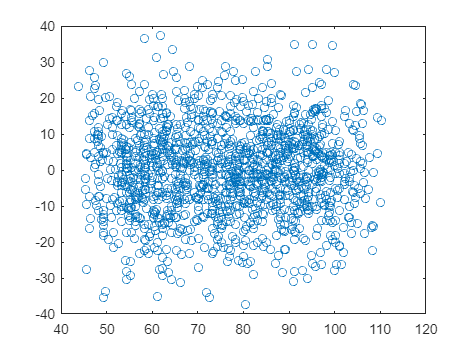


plot(ypred,r,'o')

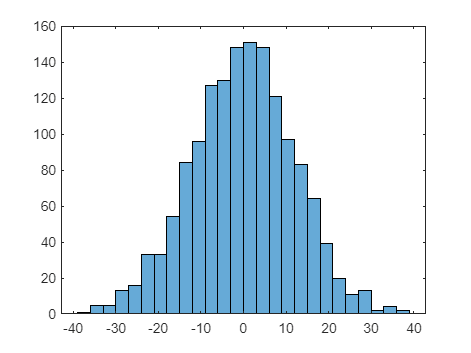

histogram(r)

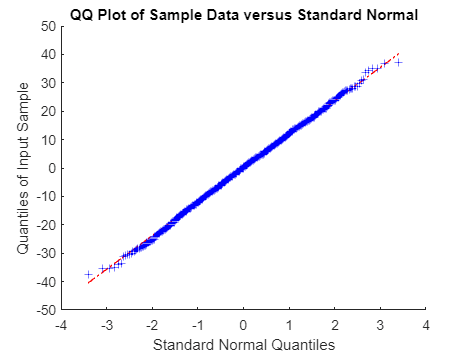

qqplot(r)

Remove Gender variable

lm = fitlm(X(:,2:3),Y)

lm = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate       SE       tStat       pValue   
                   ________    ________    ______    ___________

    (Intercept)     6.7582       1.9273    3.5066     0.00046727
    x1             0.99603     0.020574    48.412    1.3909e-308
    x2              1.7586      0.11586    15.179     1.6397e-48


Number of observations: 1500, Error degrees of freedom: 1497
Root Mean Squared Error: 12.1
R-squared: 0.636,  Adjusted R-Squared: 0.635
F-statistic vs. constant model: 1.31e+03, p-value = 0

### Intervals of confidence

X = [ones(size(income,1),1) income.Age income.Education];
[b,bint,r,rint,stats] = regress(Y,X);
[b,bint]

ans =     6.7582    2.9778   10.5387
    0.9960    0.9557    1.0364
    1.7586    1.5313    1.9859


stats

stats = 1.0e+03 *

    0.0006    1.3072         0    0.1459


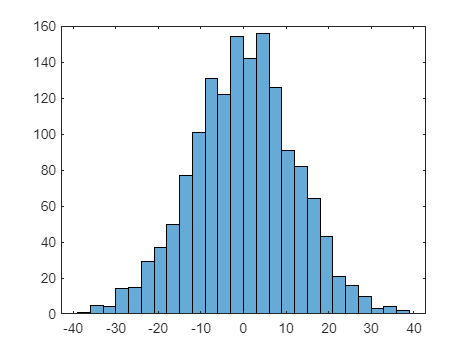


histogram(r)

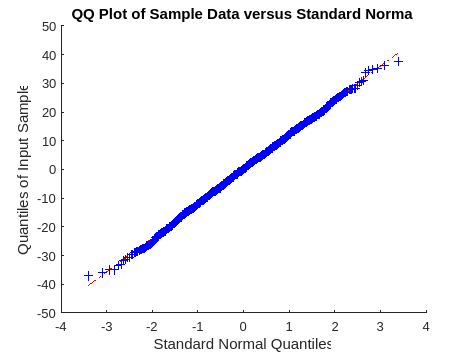

qqplot(r)

### prediction

predict(lm,[41 12])

ans = 68.6988

[y, ycur] = predict(lm,[41 12],'Prediction','curve')

y = 68.6988

ycur =    67.8310   69.5667


[y, yobs] = predict(lm,[41 12],'Prediction','observation')

y = 68.6988

yobs =    44.9887   92.4090


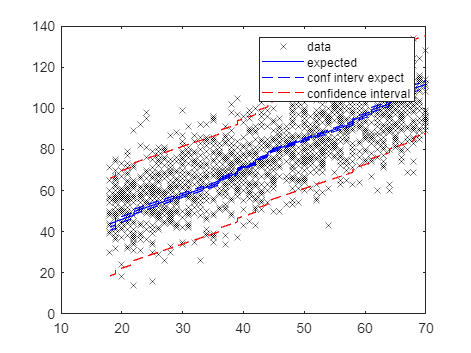


[y, y_expect] = predict(lm,[sort(income.Age) sort(income.Education)], Prediction='curve');
[y, y_observ] = predict(lm,[sort(income.Age) sort(income.Education)], Prediction='observation');

figure(100)
plot(income.Age, income.Income, 'kx')
hold on
plot(sort(income.Age), y, 'b-')
plot(sort(income.Age), y_expect(:,1), 'b--', LineWidth=0.5)
plot(sort(income.Age), y_expect(:,2), 'b--', LineWidth=0.5)
plot(sort(income.Age), y_observ(:,1), 'r--', LineWidth=0.5)
plot(sort(income.Age), y_observ(:,2), 'r--', LineWidth=0.5)
legend('data','expected','conf interv expect', '','confidence interval', '')
hold off

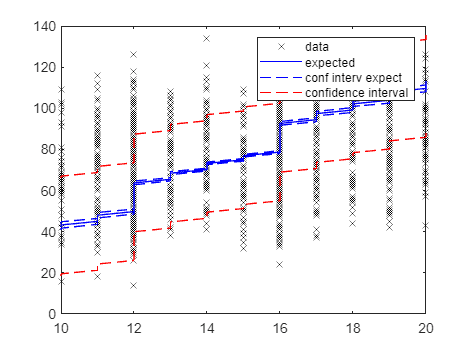


figure(100)
plot(income.Education, income.Income, 'kx')
hold on
plot(sort(income.Education), y, 'b-')
plot(sort(income.Education), y_expect(:,1), 'b--', LineWidth=0.5)
plot(sort(income.Education), y_expect(:,2), 'b--', LineWidth=0.5)
plot(sort(income.Education), y_observ(:,1), 'r--', LineWidth=0.5)
plot(sort(income.Education), y_observ(:,2), 'r--', LineWidth=0.5)
legend('data','expected','conf interv expect', '','confidence interval', '')
hold off